NOTAS DE CLASE (S6)

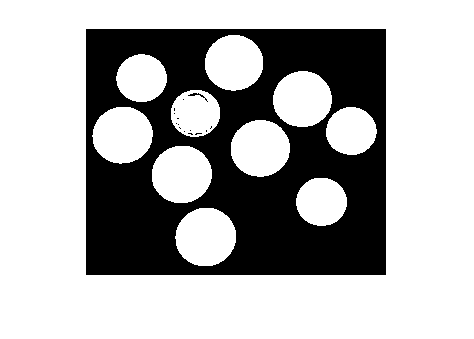

coins = imread('coins.png');
BW = coins > 100;
imshow(BW);

Crear elemento estructurant

SE = strel('disk', 2); % forma, radio

Podemos dilatar (pero los objetos se hacen grandes)

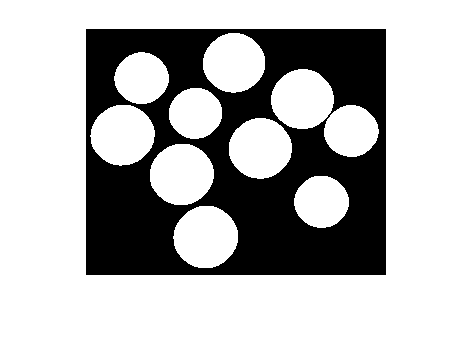

D = imdilate(BW, SE);
imshow(D);

Hacer un closing es mejor

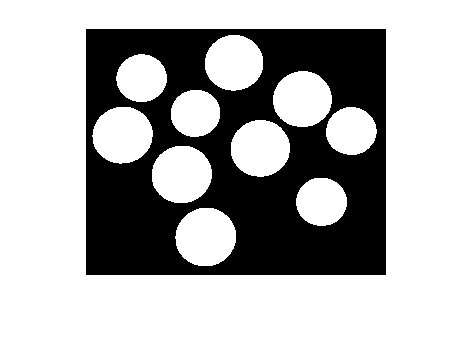

C = imclose(BW, SE);
imshow(C);

Calcular contornos con erosion y resta (contorno hacia dentro)

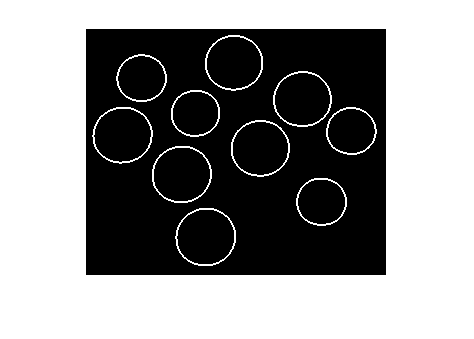

DC = C & not(imerode(C,SE));
imshow(DC);

Obtener el centro de un objeto con operaciones no lineales (erosion hasta que quede 1 erosion por hacer)

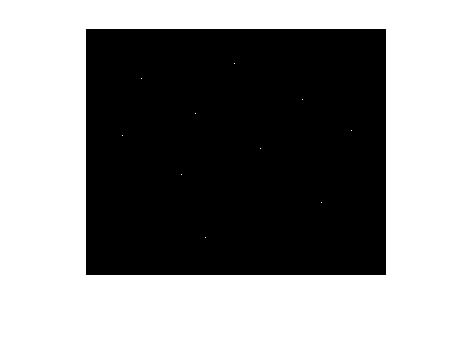

n = Inf;
S = bwmorph(C, 'shrink', n); % erosionar n veces
imshow(S);

Para crear un donut, dilatamos los centros, y restamos a la original:

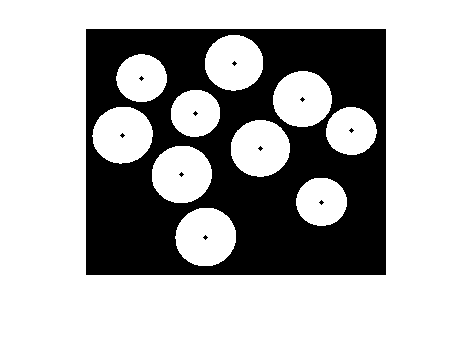

munch = imdilate(S, SE);

donut = xor(C, munch);
imshow(donut);

Ahora hay que devolverle el munch al donut:

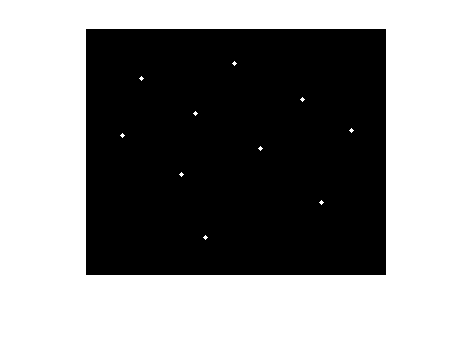

munchins = imreconstruct(S, not(donut));
imshow(IR);

Hay que unir para obtener donas rellenas:

fullDona = donut | munchins;
imshow(fullDona);

Devolver munchins sin conocer el centro:


bw = zeros(size(C));
bw(1,1) = 1;
bw = bw == 1;

RB = imreconstruct(bw, not(C));
RB = not(RB);
imshow(RB);

Propagacion de las distancias a los centros con degradado:

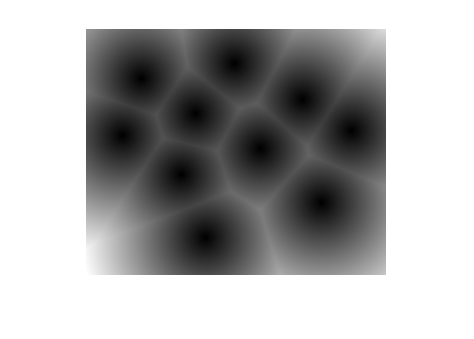

DT = bwdist(S, 'euclidean'); %la mas costosa
imshow(DT, []);

Arrositoooo

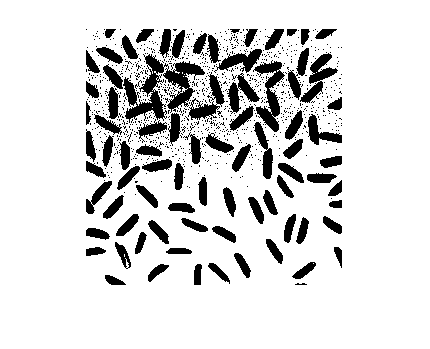

I = imread('rice.png');
BW = I < 115;
imshow(BW);

Hacemos closing para quitar manchas de culo (tierra):

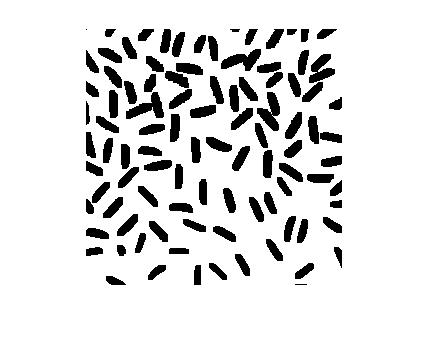

SE = strel('disk', 3); % forma, radio
C = imclose(BW, SE);
imshow(C);

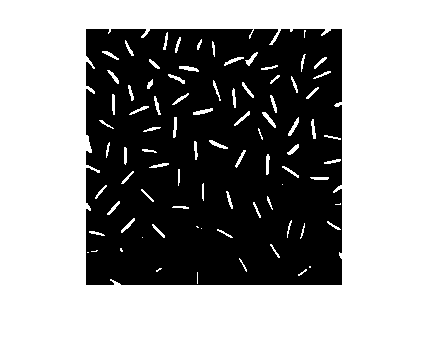


DT = bwdist(C, 'euclidean'); %la mas costosa
h = fspecial('gaussian', 5);
DTF = imfilter(DT, h);

BDT = DTF > 3.5;
imshow(BDT);

CON = bwconncomp(BDT); % eto imprime cuantos

Otra forma de aserlo xd (van a quedar mas juntos):

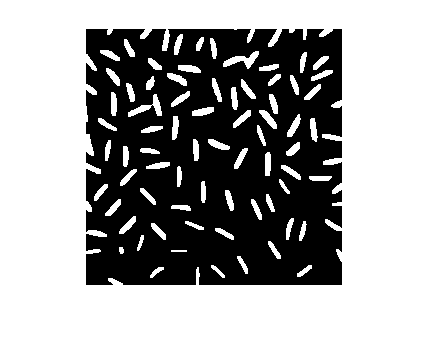

BDT = DTF > 2;
imshow(BDT);

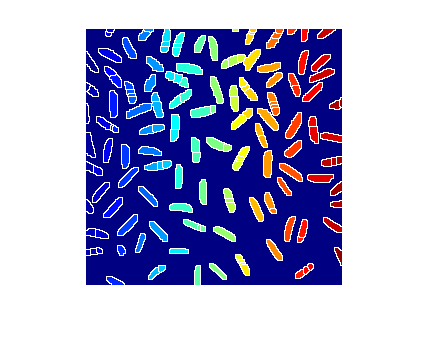

DT= floor(DT);
DT = -DT;
DT= floor(DT);
DT(DT == 0) = -Inf;
WS = watershed(DT);
RGB= label2rgb(WS);
imshow(RGB);